# **Image Segmentation**

05/04/22

--> Maxine Annel Pacheco Ramírez A01551933

--> Kristen Aideé Pérez Alvarez A00829551

-->

-->

--> 

f=imread('radiograph1.jpg'); 
f=double(f(:,:,1)); 
f=f/max(max(f));
f=imresize(f,0.15);
figure(1)
imshow(f,[]);
%Se carga la imágen y se establece lo necesario para desplegarla de manera
%correcta.

## Thresholding

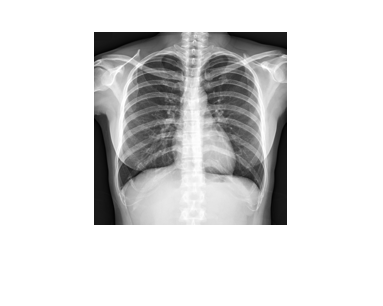

% seg1 = f > 0.5;
seg1 = f > 0.85; %Se realizan los cambios en el umbral debido a los datos aparecidos en el histograma
imshow(seg1,[])
imshow(seg1.*f,[]) %Donde no pertenece al tejido queda negro 
seg1 = f < 0.15; %Valor umbral obtenido del histograma
imshow(seg1,[])

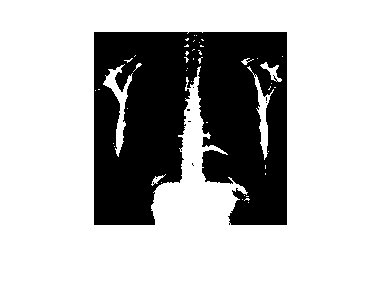

imshow(seg1.*f,[])

imhist(f)%Aqui se observa lo que esta arriba de 0.85 y abajo de 0.15.
% por esto se harán observaciones haciendo uso de estos valores umbrales.

% Use a third threshold based on the histogram


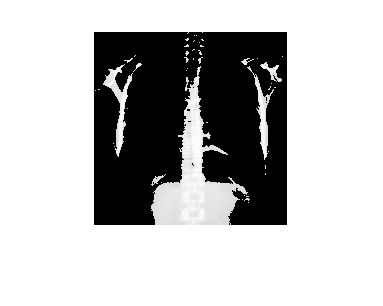

%Con este código se logra hacer segmentación al observar que tejido se

%encuentra dentro de los umbrales seleccionados.

## Otsu method

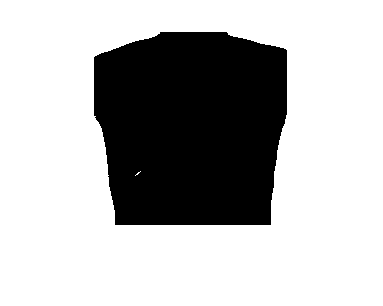

thr = graythresh(f)

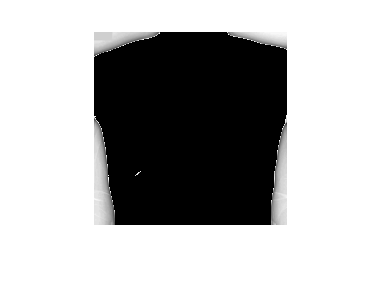

seg1 = f > thr;

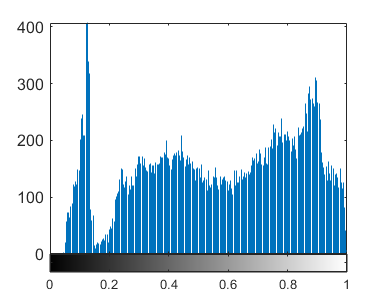

imshow(seg1,[])
dxp=[0,1;-1,0];

thr = 0.5490

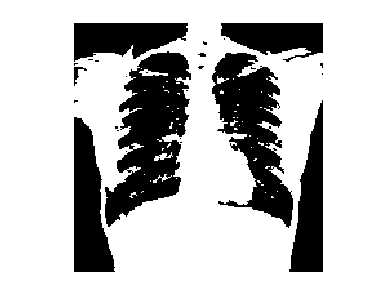

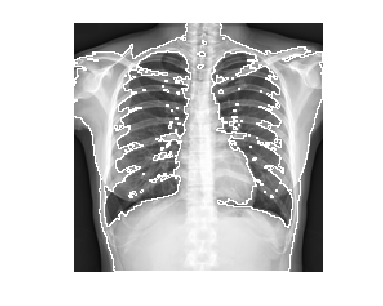

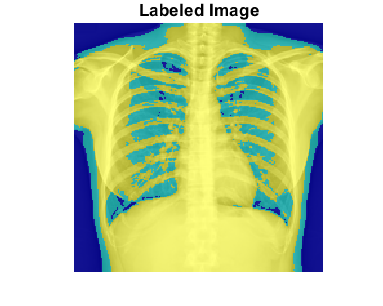

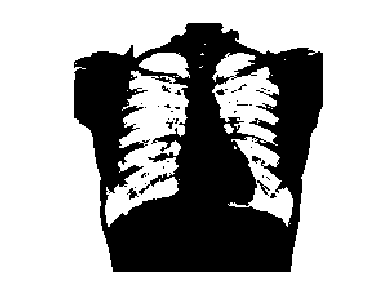

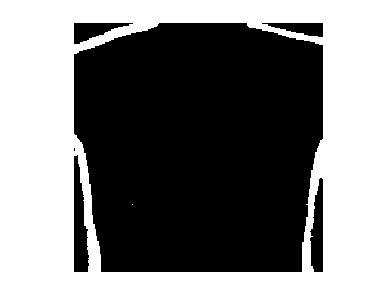

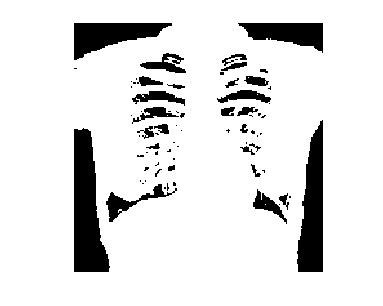

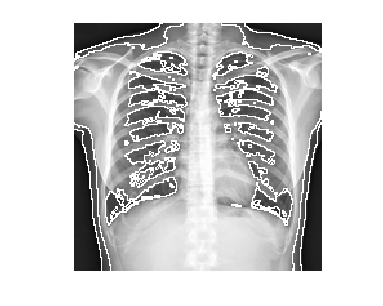

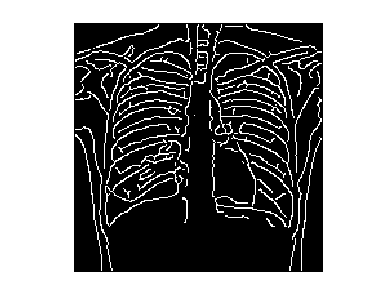

dyp=[1,0;0,-1];

edgemap = abs(conv2(seg1,dxp,'same'))+abs(conv2(seg1,dyp,'same'));
imshow(f+edgemap,[0,1]);

% Compare the otsu provided threshold vs the one you selected in the
% preview step.
% Do you trust the Otsu treshold?
% Select your own image and compute the otsu threshold

## Kmeans segmentation

[L,Centers] = imsegkmeans(int8(255*f),3);
B = labeloverlay(f,L);
imshow(B)
title("Labeled Image")
imshow(int8(255*f)<Centers(1),[])
imshow(int8(255*f)<Centers(2),[])
imshow(int8(255*f)>Centers(3),[])
edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);

% Do the same procedure but now with 5 centers.
% Is the segmentation better?

## Watershed segmentation

edgeC = edge(f,'Canny'); % Se utiliza el método Canny para detectar orillas en la imagen
imshow(edgeC,[]) % Se despliga la imagen con las orillas detectadas
D = bwdist(edgeC); % De los pixeles que no son orilla, saca la distancia de los pixeles más cercano y lo convierte en basins
imshow(D,[]) % Muestra la transformación anterior
title('Distance Transform of Binary Image')
mesh(D) % Se hace la segmentación y despliega la topografía 
L = watershed(D); % Transfroma los basins en una imagen

edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same')); % Se detectan las orillas en la topografía
imshow(f+edgemap,[0,1]); % Se despliegan las orillas detectadas en la topografía 


L(edgeC) = 0;

Display the resulting label matrix as an RGB image.

rgb = label2rgb(L,'jet',[.5 .5 .5]);
imshow(rgb)
title('Watershed Transform')

% provide an alterante segmentation based on a different edge detector